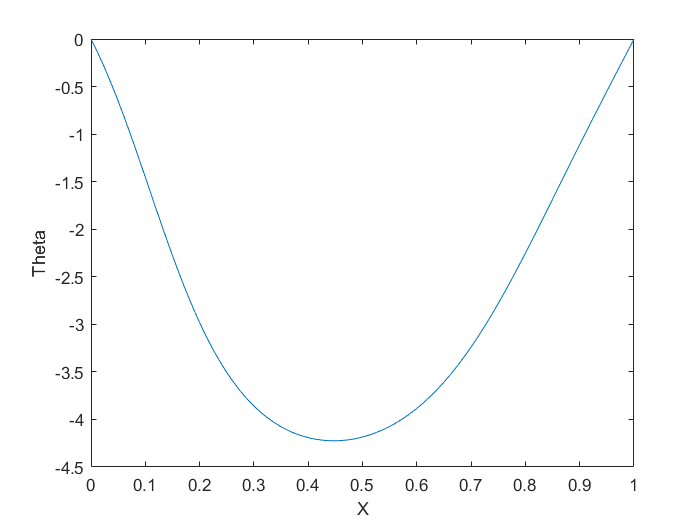

clc;
% Solving Beam ODE
B = 80;
C = 0;
S = 4;
P = 0;
Q = 0;
alpha = pi/2;
beta = pi/2;
th = 1;
Pi0 = 10000;
eps = 0;
epsilon = [];
Fz = C*sin(beta);
Fx = C*cos(beta);
j = 1;
xact = []; Thetact = [];  


xlow = 0; xhigh = 1;
xmesh = linspace(xlow,xhigh,100);
solinit = bvpinit(xmesh,@guess);
opts = bvpset('RelTol',0.1,'AbsTol',0.1);
sol = bvp4c(@(x,y) HMSMpaper(x,y,P,Q,C,S,alpha,beta,B,Pi0), @bc, solinit, opts);
xint = linspace(xlow,xhigh,100);
Sxint = deval(sol,xint);
eps=[];
j = 1;
for i = xint
    eps(j) = (1/Pi0)*((1-xint(j))*(P*cos(Sxint(1,j)) - Q*sin(Sxint(1,j))) + Fx*cos(Sxint(1,j)) + Fz*sin(Sxint(1,j)) + B*Svalue(S,xint(j))*cos(Sxint(1,j)-alpha));
    j = j+1;
end
plot(xint, Sxint(1,:));
xlabel('X');
ylabel('Theta');

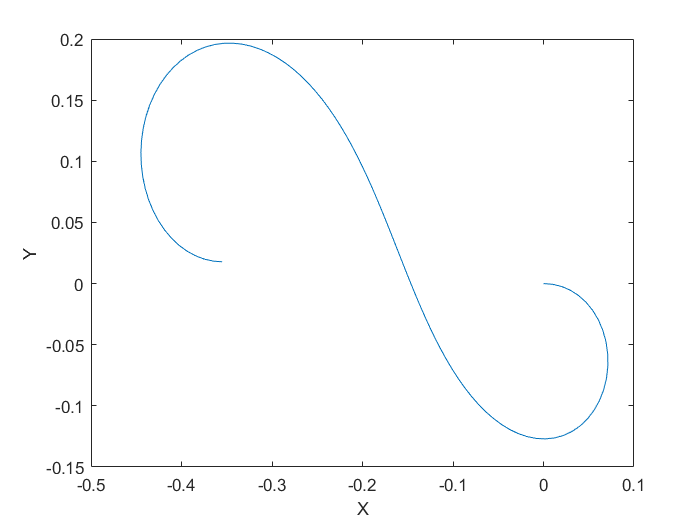



u = cumtrapz(xint, ((1+eps).*cos(Sxint(1,:))-1));
v = cumtrapz(xint, ((1+eps).*sin(Sxint(1,:))));

plot(xint+u, v);
xlabel('X');
ylabel('Y');